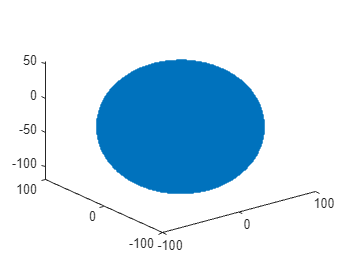

clear; clc; close all

C = [0 ,0 ,0];
R = 86;

[px,py,pz] = meshgrid(1:2*R, 1:2*R, 1:2*R);
c = C+R;

A = zeros(2*R,2*R,2*R);
A((px-c(1)).^2 + (py-c(2)).^2 + (pz-c(3)).^2 <= R^2) = 1;

[x, y, z] = ind2sub(size(A), find(A));
xyz_Data=[x, y, z]-R;
plot3(xyz_Data(:,1), xyz_Data(:,2), xyz_Data(:,3), '.');


writematrix(xyz_Data./1000,'phantom.txt','delimiter',' ')
%save('Sphere.mat',"A")